# Strømningsprocesser

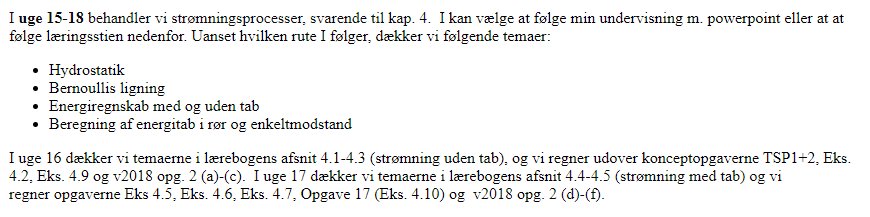

clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp");

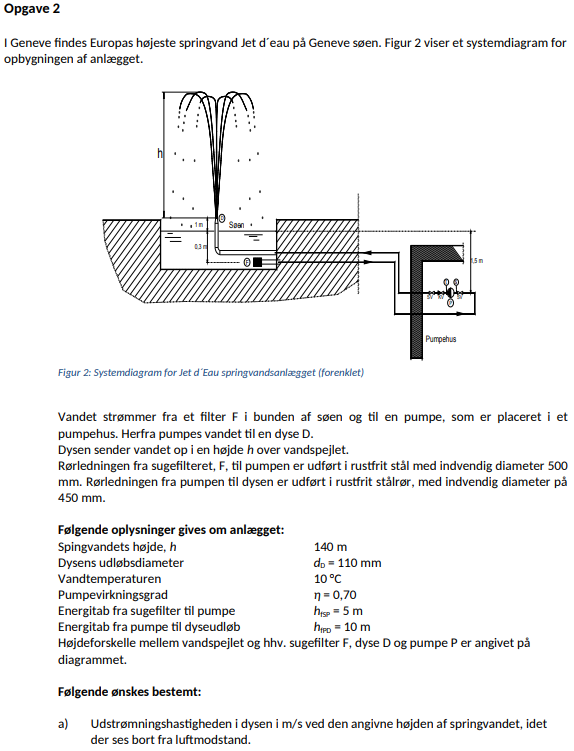

% Opgave a)


% Opgave oplysninger
d_s = 500e-3; % Rør diameter sug
d_t = 450e-3; % Rør diameter tryk


h = 140;    % Højde på springvand
d_D = 110e-3;    % Dysediameter
T = 10;    % Temperatur på vand
eta_pumpe = 0.70;    % Pumpens virkningsgrad
hf_SP = 5;    % Tab i sugeledning
hf_PD = 10;    % Tab i trykledning

dyn_vis = CP.PropsSI("V", "P", 101325, "T", 273.15 + 10,"Water"); % Vand dynamiske viskositet
dens = CP.PropsSI("D", "P", 101325, "T", 273.15 + 10,"Water"); % Vand densitet
kin_vis = dyn_vis/dens  % Kinematisk viskositet

kin_vis = 1.3063e-06


% Højder
z_F = 1.2; % Sugefilter
z_D = 2.5; % Dyse
z_P = 0; % pumpe

% Tryk
p_atm = 0;
p1 = p_atm;
p2 = p1;

% Bestem udstrømningshastigheden i dysen i m/s ved den angive højde.
% Energiligning 4.20 bruges til at løse for hastigheden i toppen
c2 = 0;


c_1 = BernuillisLigning_UdenFriktion(0,0,nan,0,z_D,142.5,dens)

Energiligning 4.20:


$$eq = g\,z_{2}+\frac{p_{2}}{\rho }+\frac{{c_{2}}^{2}}{2}=g\,z_{1}+\frac{p_{1}}{\rho }+\frac{{c_{1}}^{2}}{2}$$

---------------------------------------------------
Der løses for: c_1


$$sol = \left(\begin{array}{c} \frac{\sqrt{\rho \,{c_{2}}^{2}-2\,p_{1}+2\,p_{2}-2\,g\,\rho \,z_{1}+2\,g\,\rho \,z_{2}}}{\sqrt{\rho }}\\ -\frac{\sqrt{\rho \,{c_{2}}^{2}-2\,p_{1}+2\,p_{2}-2\,g\,\rho \,z_{1}+2\,g\,\rho \,z_{2}}}{\sqrt{\rho }} \end{array}\right)$$

---------------------------------------------------


$$OP = \left(\begin{array}{c} 52.437\\ -52.437 \end{array}\right)$$

$$c\_1 = \left(\begin{array}{c} 52.437\\ -52.437 \end{array}\right)$$

c1 = vpa(c_1(1),5)

$$c1 = 52.437$$


qv = c1 * pi * d_D^2/4;
qv = vpa(qv,3)

$$qv = 0.498$$


qm_vand = qv * dens

$$qm\_vand = 498.17367739456226656593260930366$$

% Vandhastigheder
A_sug = pi*d_s^2/4;
c_sug = vpa(qv/A_sug,3)

$$c\_sug = 2.54$$


A_tryk = pi*d_t^2/4;
c_tryk = vpa(qv/A_tryk,3)

$$c\_tryk = 3.13$$


% Hastighedshøjder
grav = 9.82;
h_sug = vpa(c_sug^2/(2*grav),3)

$$h\_sug = 0.328$$

h_tryk = vpa(c_tryk^2/(2*grav),3)

$$h\_tryk = 0.5$$


% Trykhøjder
z0 = 0.3;
p_0 = dens*grav*z0

p_0 = 2.9451e+03


z_end = 0; % ligemeget da trykket er 0
p_end = 0;
p_end = dens*p_end*z_end

p_end = 0



% z_0 og c_0 samt c_sug og c_tryk

% Energiniveau
Hf = p_0/(dens*grav) + z_F

Hf = 1.5000

H_PS = Hf - hf_SP

H_PS = -3.5000


Hd = vpa(p_end/(dens*grav) + c1^2/(2*grav) + z_D,4)

$$Hd = 142.5$$

H_PT = vpa(Hd + hf_PD,4)

$$H\_PT = 152.5$$


% Trykhøjder ved suge og trykside
P_ps = (H_PS - c_sug^2/(2*grav) - z_P)*dens*grav

$$P\_ps = -37579.367178258679110642336280439$$

P_ps_m = P_ps/(dens*grav)

$$P\_ps\_m = -3.8279583999985150022667910082232$$


P_pt = (H_PT - c_tryk^2/(2*grav) - z_P)*dens*grav

$$P\_pt = 1492197.2656915201617316782875253$$

P_pt_m = P_pt/(dens*grav)

$$P\_pt\_m = 152.00013961287124368777776446217$$

% Igen

% a)
h = 140;
z_D = 2.5

z_D = 2.5000

c1 = BernuillisLigning_UdenFriktion(0,0,nan,0, z_D, h + z_D,dens);

Energiligning 4.20:


$$eq = g\,z_{2}+\frac{p_{2}}{\rho }+\frac{{c_{2}}^{2}}{2}=g\,z_{1}+\frac{p_{1}}{\rho }+\frac{{c_{1}}^{2}}{2}$$

---------------------------------------------------
Der løses for: c_1


$$sol = \left(\begin{array}{c} \frac{\sqrt{\rho \,{c_{2}}^{2}-2\,p_{1}+2\,p_{2}-2\,g\,\rho \,z_{1}+2\,g\,\rho \,z_{2}}}{\sqrt{\rho }}\\ -\frac{\sqrt{\rho \,{c_{2}}^{2}-2\,p_{1}+2\,p_{2}-2\,g\,\rho \,z_{1}+2\,g\,\rho \,z_{2}}}{\sqrt{\rho }} \end{array}\right)$$

---------------------------------------------------


$$OP = \left(\begin{array}{c} 52.437\\ -52.437 \end{array}\right)$$


% b)
d_D = 110e-3;

A = pi*d_D^2/4;
qv = vpa(max(c1)*A,4);

qm_vand = qv*dens;

% c)

% Fluidhastigheder
ds = 500e-3;
dt = 450e-3;

cs = vpa(qv/(pi*ds^2/4),4);
ct = vpa(qv/(pi*dt^2/4),4);

% indløb h, suge h, tryk h, udløb h
hs = [1.2, 0, 0, 2.5];

% Hastigheder
% før pumpe, ind i pumpe, ud af pumpe, endeligt udløb
cs = vpa([0, cs, ct, max(c1)],4);


% Trykhøjder
z_ind = 0.3; % m
z_ud = 0; % m

p_ind = z_ind * dens * grav;
p_ind_m = p_ind/(dens*grav)

p_ind_m = 0.3000


p_ud = z_ud * dens * grav;
p_ud_m = p_ud/(dens*grav);

ths = [p_ind_m p_ud_m]

ths =     0.3000         0





% Tab
tab = [5,10] 

tab =      5    10



% Vigtigt at s

op = TrykSkema_tabpos_1og3(hs, cs, tab, ths,dens);

Energiregnskabet for trykforholdene, der fremgår nedenunder, er regnet udfra energiniveauet og trykkene i systemet. Følgende formler er brugt:
---------------------------------------------------
Fluidhastigheder (hvor i enten er sug eller tryk for pumpen):


$$c_{i}=\frac{q_{v}}{\frac{\pi }{4}\,{d_{i}}^{2}}$$

---------------------------------------------------
Hastighedshøjder (hvor i enten er sug eller tryk for pumpen):


$${\mathrm{Hh}}_{i}=\frac{{c_{i}}^{2}}{2\,g}$$

---------------------------------------------------
Trykhøjder:


$${\mathrm{pH}}_{i}=\frac{p}{\rho \,g}$$

---------------------------------------------------
Energiniveauer (hvor i er pkt 1,2... n i systemet):


$$H_{i}=\frac{p_{i}}{\rho \,g}+\frac{{c_{i}}^{2}}{2\,g}+z_{i}$$

---------------------------------------------------
Energiniveauer for tab i systemet:


$$\mathrm{H\_}\left(\mathrm{i}+1\right)=H_{i}-H_{\mathrm{tab}}$$

---------------------------------------------------
Trykhøjder for pumpen:


$$\frac{p_{i}}{\rho \,g}=H_{i}-\frac{{c_{i}}^{2}}{2\,g}-z_{i}$$

$$p_{i}=\left(H_{i}-\frac{{c_{i}}^{2}}{2\,g}-z_{i}\right)\,\rho \,g$$

---------------------------------------------------
       Deskriptor        Punkt 1    Punkt 2    Punkt 3    Punkt 4    Enhed
    _________________    _______    _______    _______    _______    _____

    "Trykhøjde"          0.3        -3.83       152.0      0         "m"  
    "Hastighedshøjde"    0          0.328       0.5        140.0     "m"  
    "Højde, z"           1.2        0           0          2.5       "m"  
    "Energiniveau"       1.5        -3.5        152.0      142.0     "m"  
    "Energitab"          0          -5.0        156.0      -10.0     "m"  
    "Hastighed"          0          2.54        3.13       52.4      "m/s"
    "Tryk"               0.0295     -0.376      14.9       0         "bar"



H_pumpe = 156; % Fra tabellen



% Effekten beregnes ud fra liging 4.26
eta_pumpe = 0.7;
P_el = qv*dens*H_pumpe*grav/eta_pumpe * 1e-3

$$P\_el = 1090.231742681519349377402458438$$

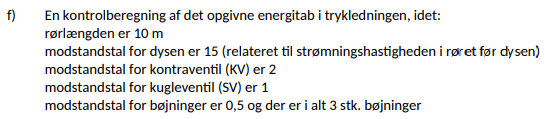

ct = ct;
L = 10;
ks = 0.005e-3;
dt = 0.45;

Re = 1.081e6

Re = 1081000


% gæt
lam_guess = 105;
lambda_ny = 1/((1.74 - 0.87*log(2*ks/dt + 18.7/(Re*sqrt(lam_guess))))^2)

lambda_ny = 0.0083

iter = 0;

while lambda_ny/lam_guess ~= 1
    iter = iter+1

    lambda_ny = 1/((1.74 - 0.87*log(2*ks/dt + 18.7/(Re*sqrt(lam_guess))))^2)

    lam_guess = 1/((1.74 - 0.87*log(2*ks/dt + 18.7/(Re*sqrt(lambda_ny))))^2)

    if iter > 50
        break
    end

end

iter = 1

lambda_ny = 0.0083

lam_guess = 0.0121

iter = 2

lambda_ny = 0.0117

lam_guess = 0.0117

iter = 3

lambda_ny = 0.0117

lam_guess = 0.0117

iter = 4

lambda_ny = 0.0117

lam_guess = 0.0117

iter = 5

lambda_ny = 0.0117

lam_guess = 0.0117

iter = 6

lambda_ny = 0.0117

lam_guess = 0.0117

iter = 7

lambda_ny = 0.0117

lam_guess = 0.0117

iter = 8

lambda_ny = 0.0117

lam_guess = 0.0117


lambda_ny

lambda_ny = 0.0117

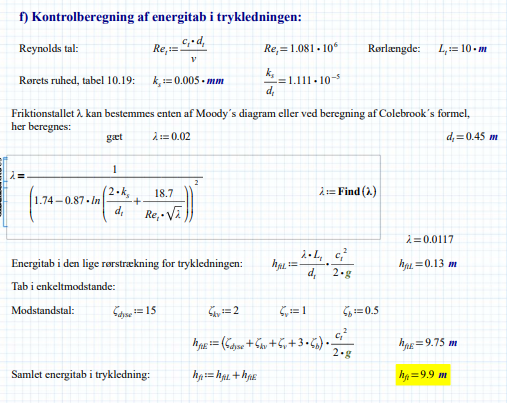

hs = [5.4, 4.4, 0, 1.7];
cs = [0, 5.1, 1.3, 0];
tabs = [1.5, 2.0];
ths = [0, 0];

op = TrykSkema_tabpos_1og2(hs, cs, tabs, ths, dens);

Energiregnskabet for trykforholdene, der fremgår nedenunder, er regnet udfra energiniveauet og trykkene i systemet. Følgende formler er brugt:
---------------------------------------------------
Fluidhastigheder (hvor i enten er sug eller tryk for pumpen):


$$c_{i}=\frac{q_{v}}{\frac{\pi }{4}\,{d_{i}}^{2}}$$

---------------------------------------------------
Hastighedshøjder (hvor i enten er sug eller tryk for pumpen):


$${\mathrm{Hh}}_{i}=\frac{{c_{i}}^{2}}{2\,g}$$

---------------------------------------------------
Trykhøjder:


$${\mathrm{pH}}_{i}=\frac{p}{\rho \,g}$$

---------------------------------------------------
Energiniveauer (hvor i er pkt 1,2... n i systemet):


$$H_{i}=\frac{p_{i}}{\rho \,g}+\frac{{c_{i}}^{2}}{2\,g}+z_{i}$$

---------------------------------------------------
Energiniveauer for tab i systemet:


$$\mathrm{H\_}\left(\mathrm{i}+1\right)=H_{i}-H_{\mathrm{tab}}$$

---------------------------------------------------
Trykhøjder for pumpen:


$$\frac{p_{i}}{\rho \,g}=H_{i}-\frac{{c_{i}}^{2}}{2\,g}-z_{i}$$

$$p_{i}=\left(H_{i}-\frac{{c_{i}}^{2}}{2\,g}-z_{i}\right)\,\rho \,g$$

---------------------------------------------------
       Deskriptor        Punkt 1    Punkt 2    Punkt 3    Punkt 4    Enhed
    _________________    _______    _______    _______    _______    _____

    "Trykhøjde"            0        -1.82       1.81       0         "m"  
    "Hastighedshøjde"      0        1.32        0.086      0         "m"  
    "Højde, z"             5.4      4.4         0          1.7       "m"  
    "Energiniveau"         5.4      3.9         1.9        1.7       "m"  
    "Energitab"            0        -1.5        -2.0       -0.2      "m"  
    "Hastighed"            0        5.1         1.3        0         "m/s"
    "Tryk"                 0        -0.179      0.178      0         "bar"



2

ans = 2

2

ans = 2

2

ans = 2

2

ans = 2

2

ans = 2